clear all;clc
password=input("enter a strong password that has Capital letter,digit,special symbol and at leat 8 character long",'s')

password = 'Password123!'

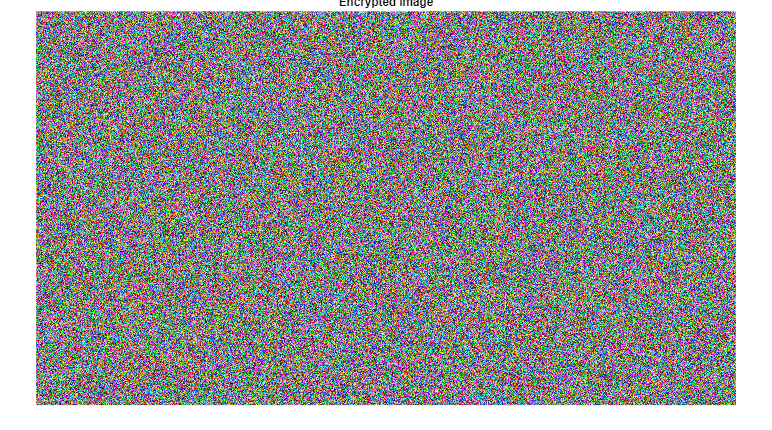

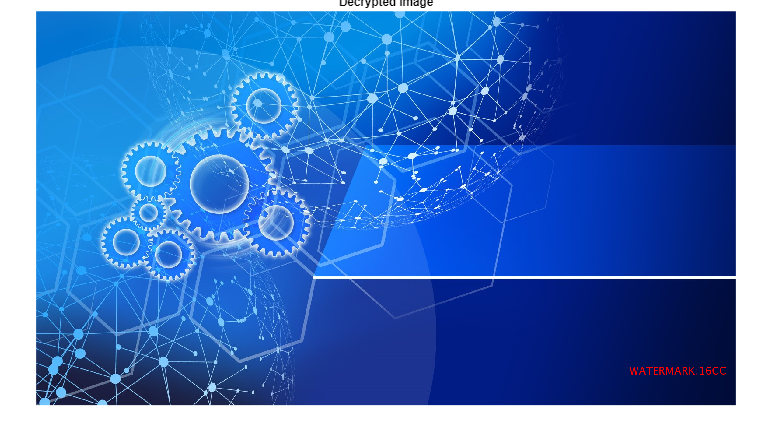

tic
function decrypted_image = image_decryption_with_error_detection(encrypted_image, password)
    
    % Read the encrypted color image
    img = imread(encrypted_image);
    [rows, cols, channels] = size(img);

    % Convert the password into a numeric seed
    password_seed = double(sum(password .* (1:numel(password))));
    
    % Initialize the decrypted image
    decrypted_image = zeros(rows, cols, channels, 'uint8');
    
    % For each channel, perform decryption using the transformations
    for c = 1:channels
        % Extract the encrypted channel
        encrypted_channel = img(:,:,c);
        
        % Reverse the column shuffle
        rng(password_seed * (c + 3), 'twister');
        col_order = randperm(cols);
        [~, reverse_col_order] = sort(col_order);
        unshuffled_channel_cols = encrypted_channel(:, reverse_col_order);
        
        % Reverse the row shuffle
        rng(password_seed * (c + 2), 'twister');
        row_order = randperm(rows);
        [~, reverse_row_order] = sort(row_order);
        unshuffled_channel = unshuffled_channel_cols(reverse_row_order, :);
        
        % Generate the same XOR mask for this channel
        rng(password_seed * (c + 1), 'twister');
        xor_mask = uint8(randi([0, 255], rows, cols));
        
        % Reverse the XOR operation to retrieve the original channel
        decrypted_image(:,:,c) = bitxor(unshuffled_channel, xor_mask);
    end
    
    % Save the decrypted image
    imwrite(decrypted_image, 'C:/Users/azhar/OneDrive/Pictures/decrypted_image.png');
    
    
    % Display the decrypted image
    figure;
    imshow(encrypted_image); title('Encrypted Image');
    figure;
    imshow(decrypted_image); title('Decrypted Image');
    
end
image_decryption_with_error_detection('C:/Users/azhar/OneDrive/Pictures/encrypted_image.png', password);

toc

Elapsed time is 2.376503 seconds.
